%写一个具体的流程图给老师

% 窗长和频率相关
% rigsure加平滑
% 2% control chart
% bayes threshold

clc; clear;
warning off;

fs=500;%采样频率


%{
% % load all files in selected folder
ftype='.txt';
pname='/Users/yskj/Desktop/项目/LFPDecoding/fixed_data/';

txtfile=[pname,'*',ftype];
file=dir(txtfile);
nside=size(file,1);

iside = 10;

fname=file(iside).name
impfilename=[pname,fname];
sori=importdata(impfilename,'\t',1);

sgpi=sori.data(:,2);
fsResample = 256;
sgpiResample=resample(sgpi,fsResample,fs);

signal = sgpiResample;
%}

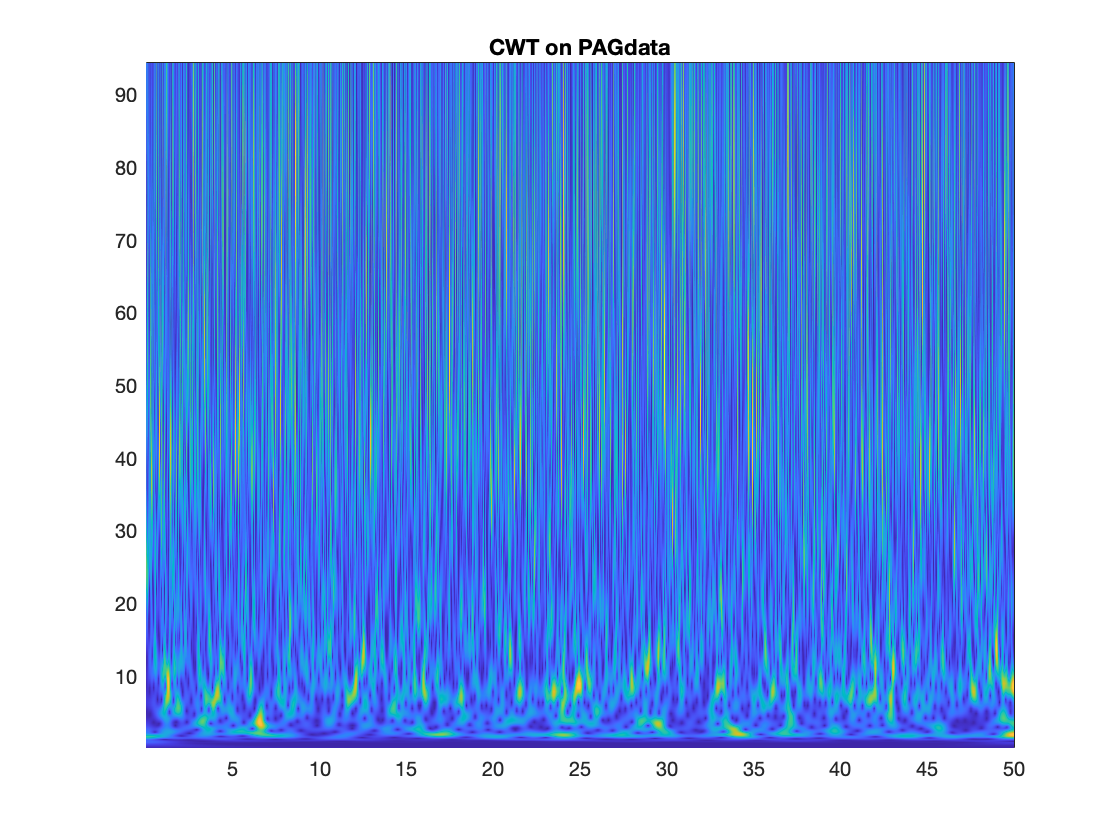

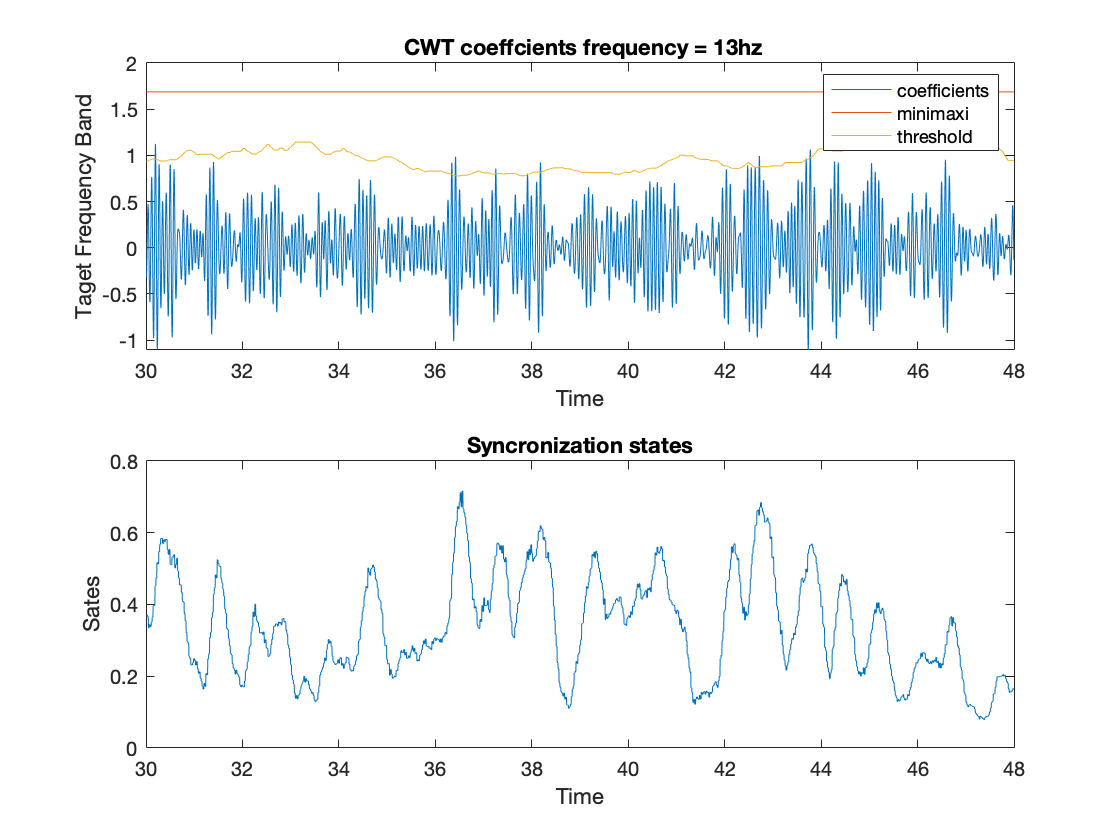

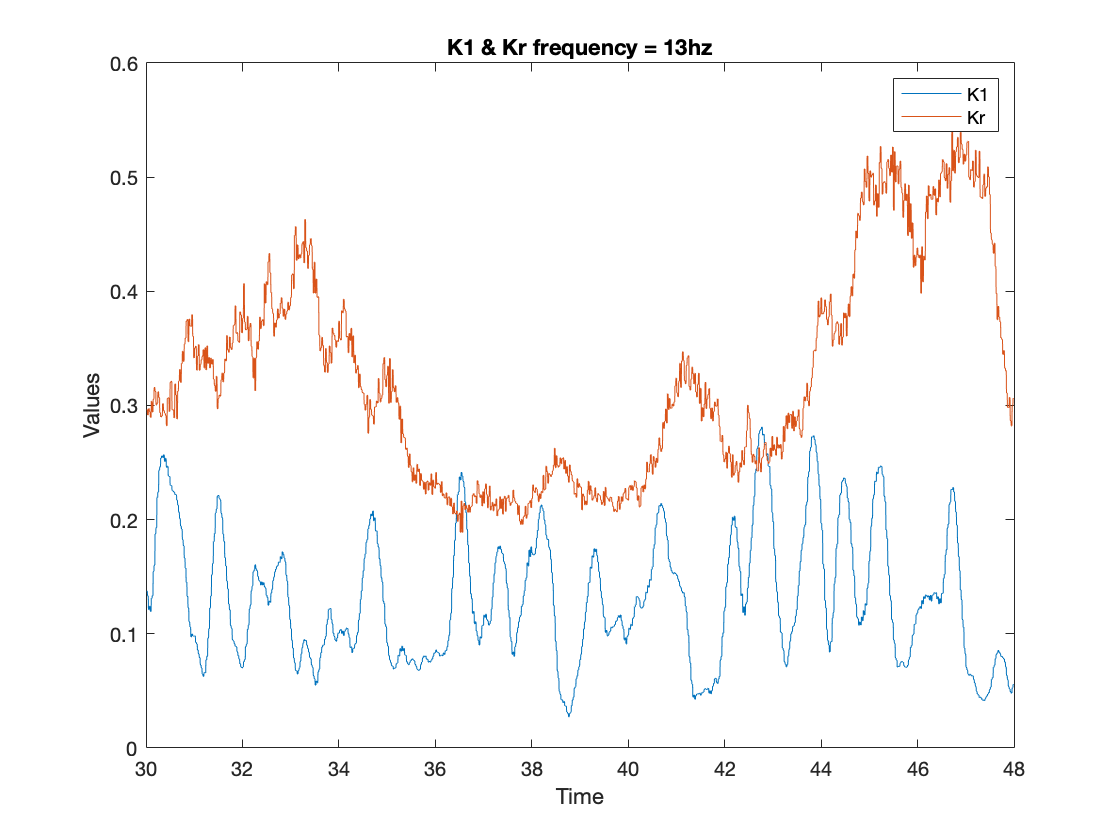

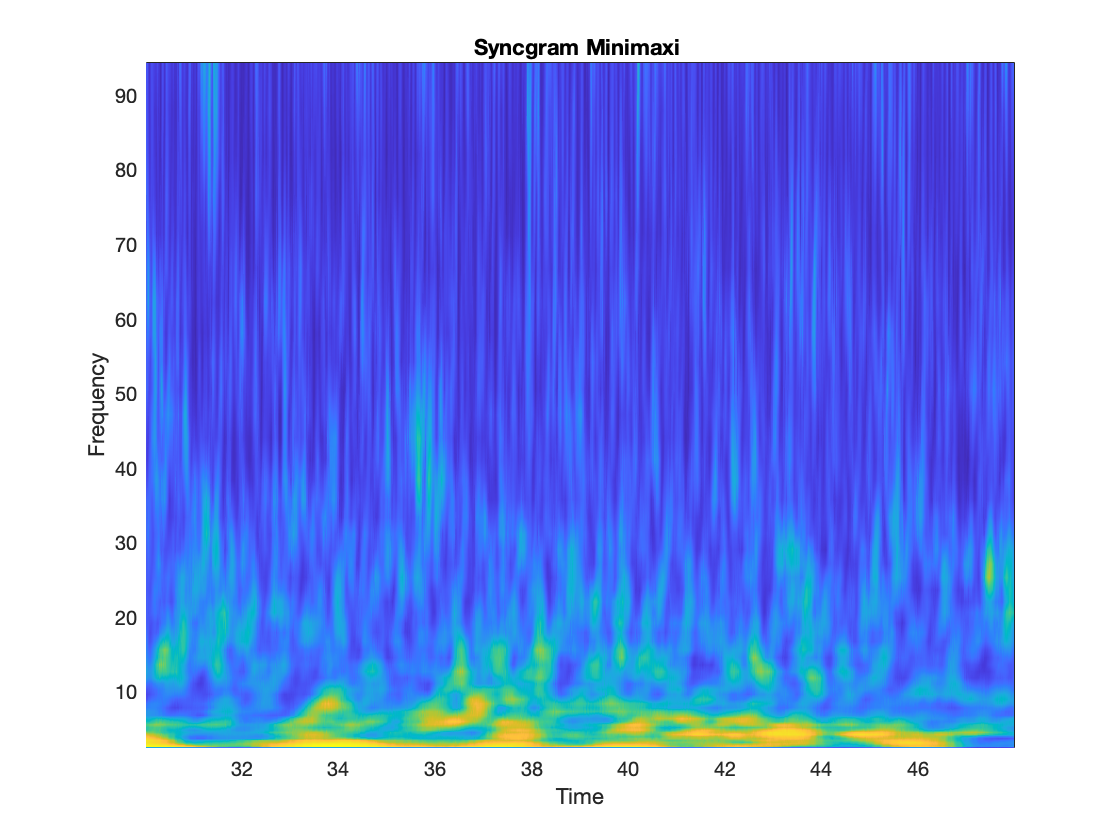

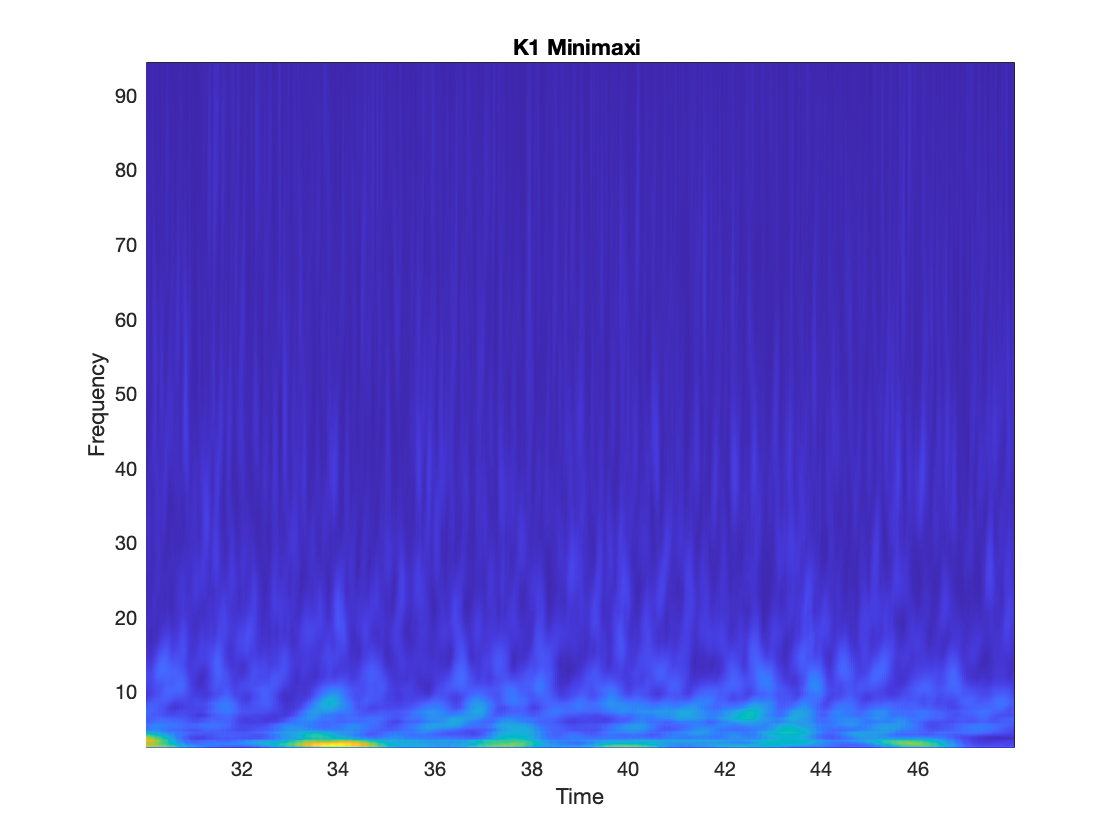

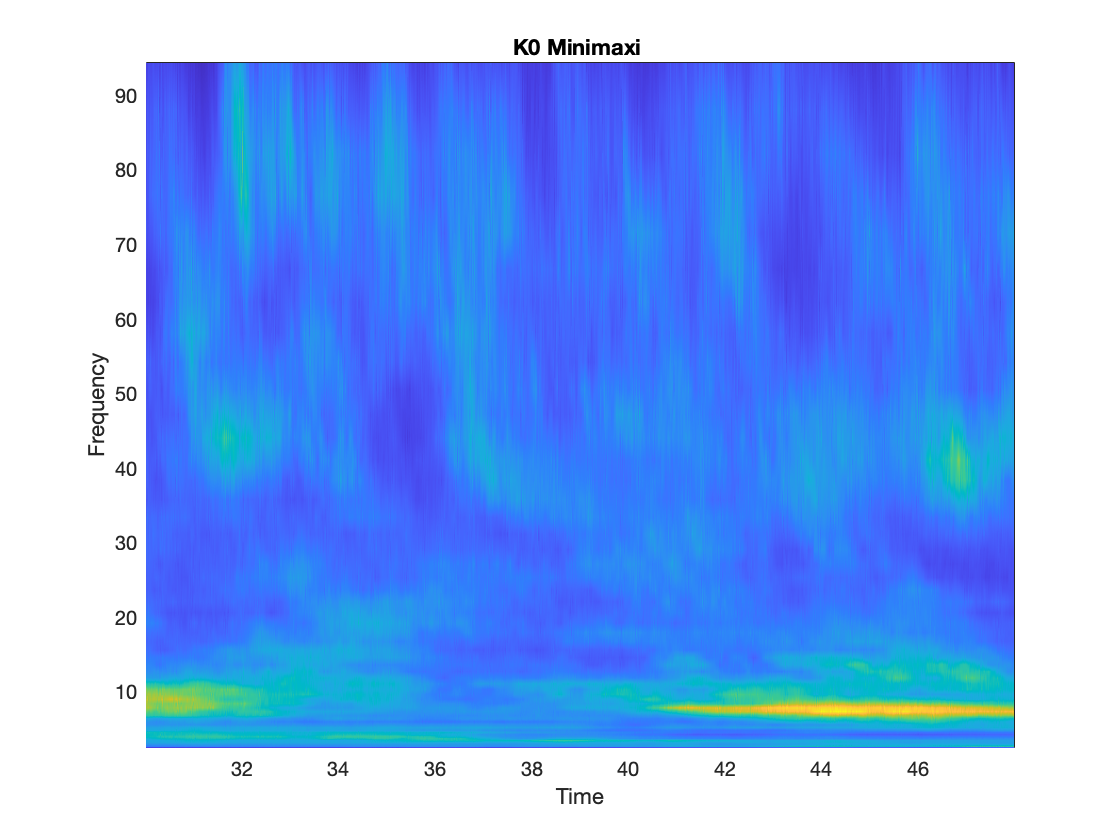

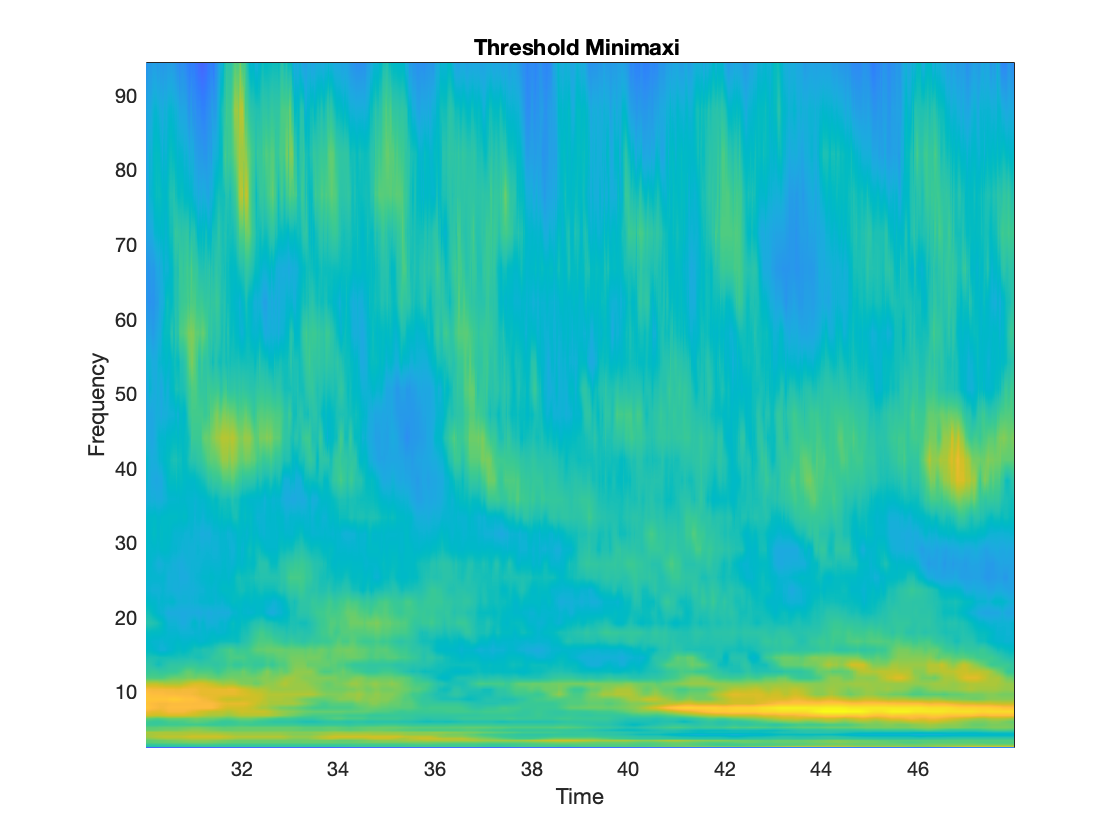

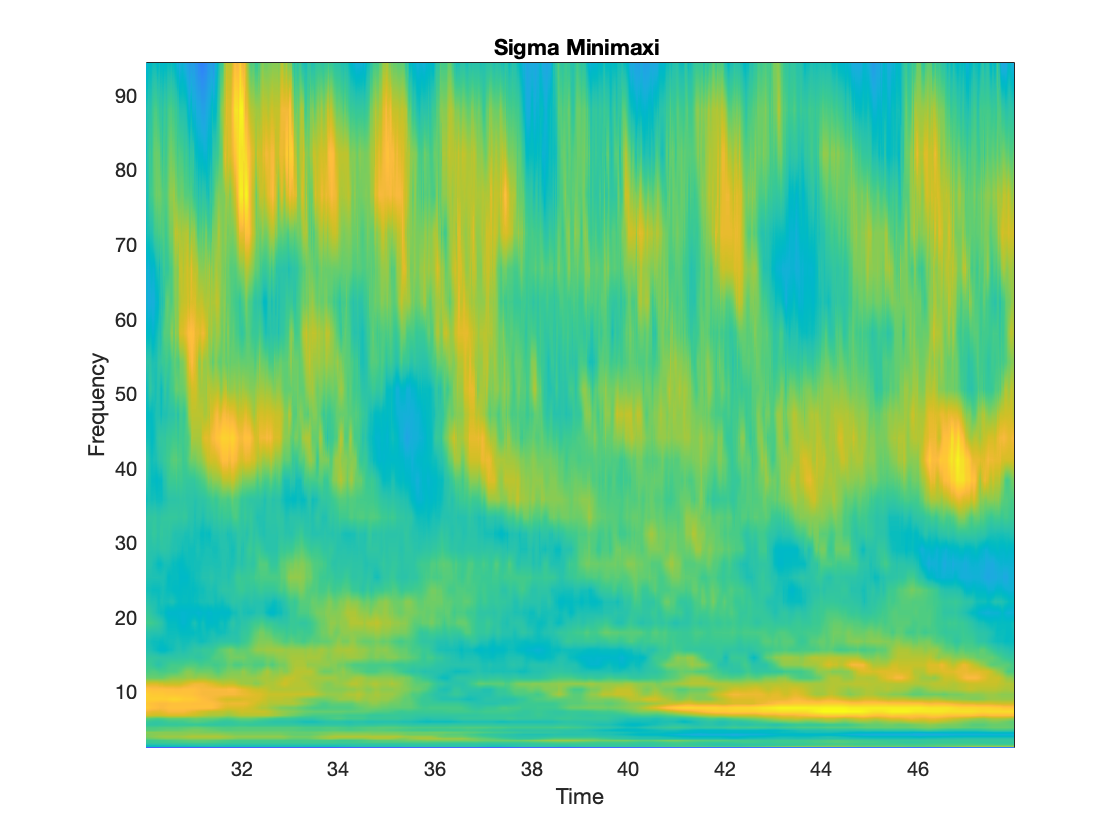



load("LFP_delete15.mat");
sPAG=LFP_delete15(:,1);
fsResample = 256;
sPAGResample=resample(sPAG,fsResample,fs);

signal = sPAGResample;

%2-4:  fsresample = 256;node=[6 6];
%4-8:  fsresample = 256;node=[6 5];
%8-16: fsresample = 256;node=[6 4];
%16-32:fsresample = 256;node=[6 3];


%6-12 :fsresample = 384;node=[5 5];
%12-24:fsresample = 384;node=[5 4];

%layerNum = node(1);
%FrequencyBand = node(1);


[states, tVector] = NeuralSynCWT(signal, fsResample);

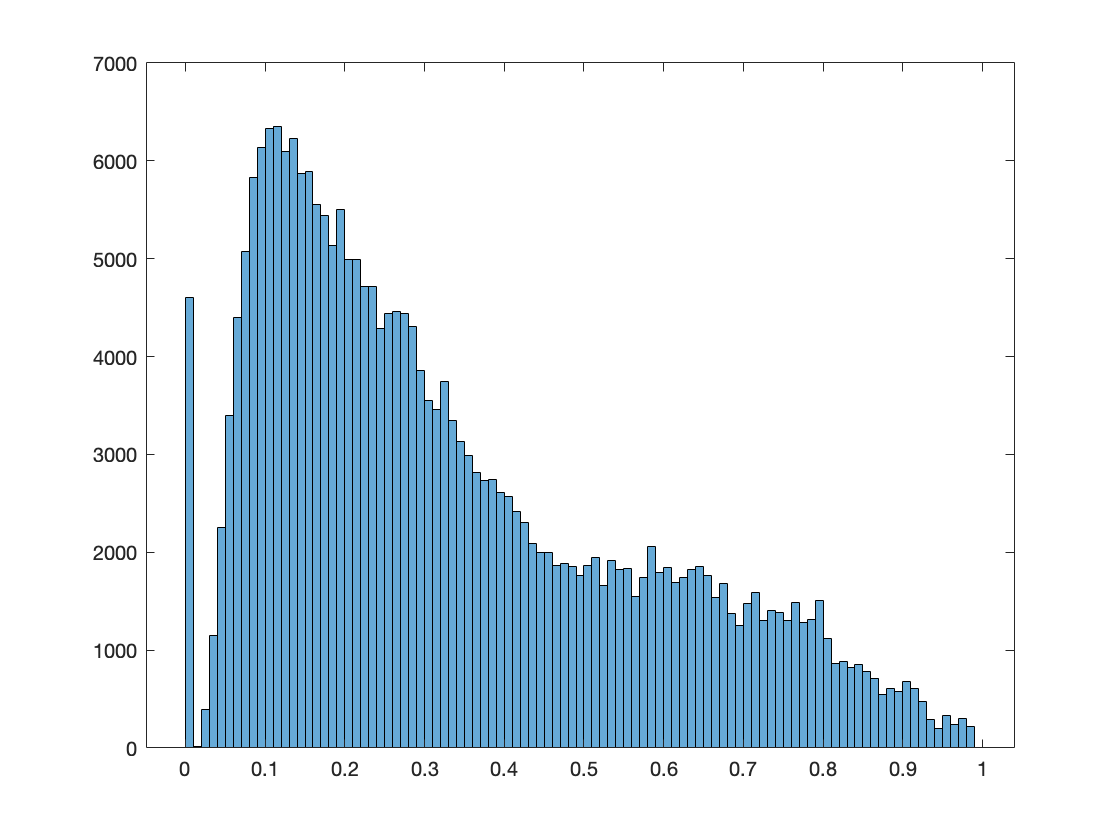



figure;
h1 = histogram(states);

title(['Syncronization Metric Histogram window = ',num2str(1/centerFreq * 60),'s']);

Unrecognized function or variable 'centerFreq'.